# 试凑法

clc;Gp = tf(100,[1,3,0]) %系统传递函数


Gp =
 
     100
  ---------
  s^2 + 3 s
 
Continuous-time transfer function.



flag = 1;
for Kp = 0.1:0.1:10
    if flag == 0
        break;
    end
    for Ki = 10:-0.1:1
        if flag == 0
            break;
        end
        for Kd = 0.1:0.1:0.5
            Gc = tf([Kd,Kp,Ki],[1,0]);
            G = feedback(Gp*Gc,1); % 计算控制器闭环传递函数
            
            [y,t] = step(G); % y、t分别为阶跃响应幅值和时间
            C = dcgain(G); % C为稳态值
            
            [Y,k] = max(y); Mp = 100 * (Y-C)/C; % Mp超调量
            
            i = length(t);
            
            while (y(i)>0.98*C)&&(y(i)<1.02*C)
                i = i - 1;
            end
            ts = t(i); % ts 是稳态时间
            
            if abs(Mp)<10 && ts <= 0.19 % 超调小于10%，稳态时间小于2s
                flag = 0;
                ys = step(G,ts);
                ess = 1 - ys;Ep = ess(end); % 稳态误差
                disp(['Kp:',num2str(Kp),','...
                      'Ki:',num2str(Ki),','...
                      'Kd:',num2str(Kd),';']);
                disp(['Mp:',num2str(Mp),'%,'...
                      'ts:',num2str(ts),'s,'...
                      'Ep:',num2str(Ep*100),'%;']);
                break;
            end
        end
    end
end

Kp:0.6,Ki:1.8,Kd:0.5;


Mp:0.13152%,ts:0.17831s,Ep:2.0015%;


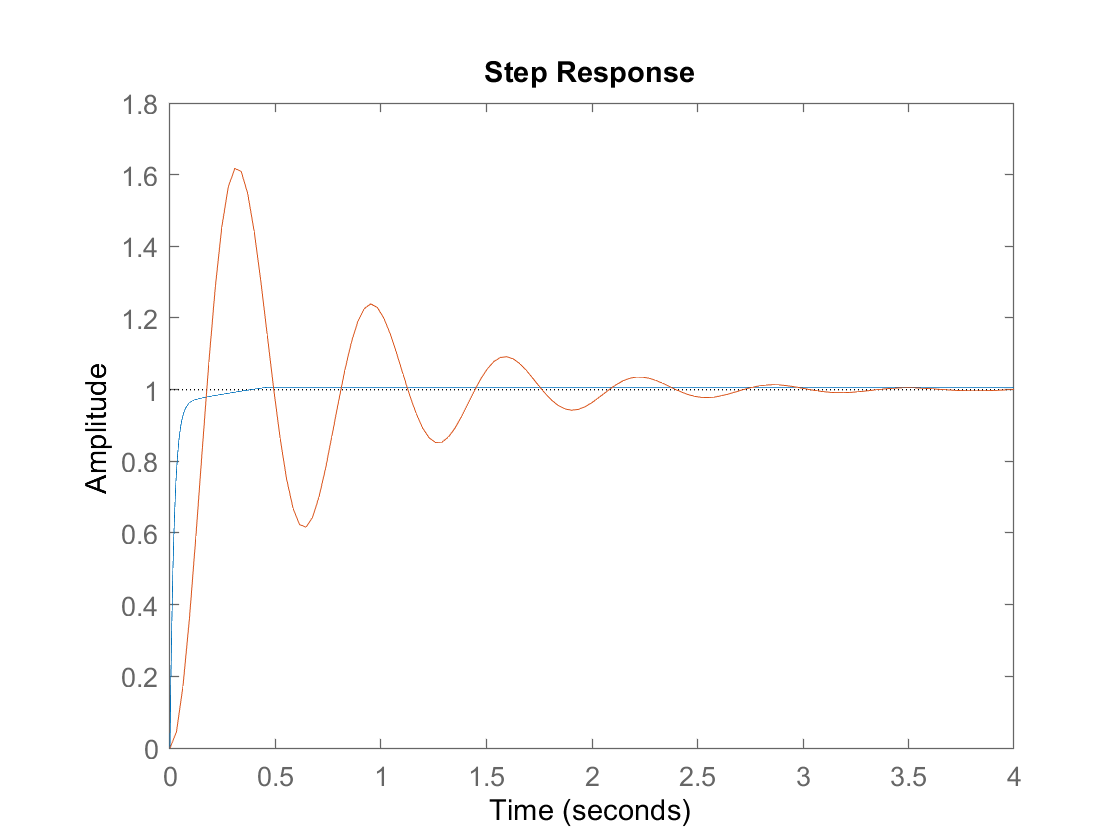

% 原系统响应
if flag == 1
    disp('Failed to search!');
end
G2 = feedback(Gp,1);
step(G);hold on;step(G2);